## Part 1: Noise

#### Exercise 1: (Error measures)

We can compare images very well with our eyes. Alternatively, we would like to compare images analytically. For this purpose, various error measurements are examined in the following.

We load the image` capybara.png `and add Gaussian noise with variance $\sigma = 0.01 ,~0.05,~0.1,~0.2,~0.4
$.

Now it is your task to add the error measures 

- MAE (Mean absolute error)               $MAE = \frac1N \|u-v\|_1$

- MSE (Mean square error)                 $MSE = \frac1N \| u-v \|_2^2$

- PSNR (Peak signal to noise ratio)    $PSNR = 10\cdot\log_{10} \left( \frac{(\max(u)-\min(u))^2}{MSE} \right)$

in the matlab script of the function` ErrorMeasure(f,u,method)`. Then look at the results. What is the difference between the known error measures MAE / MSE and the PSNR which is often used in signal and image processing.

% Load the capybara.png image and transform the values to [0,255]
img= rgb2gray(double(imread("capybara.png"))/255)

img =     0.7305    0.7266    0.7203    0.7086    0.7097    0.7097    0.7047    0.7047    0.7047    0.7047    0.7047    0.7016    0.7055    0.7095    0.7095    0.7095    0.7125    0.7086    0.7047    0.7086    0.7086    0.7095    0.7046    0.7046    0.7046    0.7046    0.7046    0.7055    0.7055    0.7055    0.7055    0.7016    0.7007    0.7047    0.7086    0.7047    0.7047    0.7047    0.6977    0.6977    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016
    0.7266    0.7227    0.7164    0.7086    0.7097    0.7097    0.7047    0.7047    0.7047    0.7047    0.7047    0.7016    0.7055    0.7095    0.7095    0.7095    0.7125    0.7086    0.7047    0.7086    0.7086    0.7086    0.7060    0.7060    0.7060    0.7060    0.7060    0.7055    0.7055    0.7055    0.7055    0.7016    0.7007    0.7047    0.7086    0.7047    0.7047    0.7047    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016    0.7016   

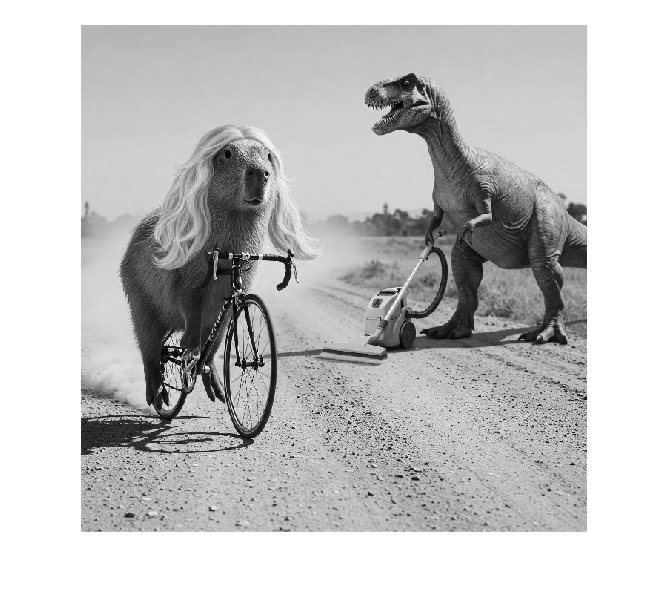

figure
imshow(img)

% adding Gaussian noise of different variances and plot it
fig=figure;
fig.Position(3:4) = [3000,2000];
subplot(2,3,1);
imshow(img);
xlabel("Original");
sigma=[0.01,0.05,0.1,0.2,0.4];

for i=1:length(sigma)
    noisyImg=imnoise(img,"gaussian",0,sigma(i)^2);
    subplot(2,3,i+1);
    imshow(noisyImg);
    xlabel(["$\sigma$=",num2str(sigma(i),"%0.2f")],"Interpreter","latex");
end

Adding MSE,MAE,PSNR, error measure to the ErrorMeasure to the Error Measure.m Matlab function script and test them on the previous messages.

methods=["MAE","MSE","PSNR"];
for i=1:length(sigma)
    noisyImg=imnoise(img,"gaussian",0,sigma(i)^2);
    for j=1:length(methods)
        E(j,i)=ErrorMeasure(noisyImg,img,methods(j))
    end
end

E = 0.0080

E =     0.0080
    0.0001


E =     0.0080
    0.0001
   40.0005


E =     0.0080    0.0399
    0.0001         0
   40.0005         0


E =     0.0080    0.0399
    0.0001    0.0025
   40.0005         0


E =     0.0080    0.0399
    0.0001    0.0025
   40.0005   26.0279


E =     0.0080    0.0399    0.0788
    0.0001    0.0025         0
   40.0005   26.0279         0


E =     0.0080    0.0399    0.0788
    0.0001    0.0025    0.0096
   40.0005   26.0279         0


E =     0.0080    0.0399    0.0788
    0.0001    0.0025    0.0096
   40.0005   26.0279   20.1570


E =     0.0080    0.0399    0.0788    0.1472
    0.0001    0.0025    0.0096         0
   40.0005   26.0279   20.1570         0


E =     0.0080    0.0399    0.0788    0.1472
    0.0001    0.0025    0.0096    0.0328
   40.0005   26.0279   20.1570         0


E =     0.0080    0.0399    0.0788    0.1472
    0.0001    0.0025    0.0096    0.0328
   40.0005   26.0279   20.1570   14.8428


E =     0.0080    0.0399    0.0788    0.1472    0.2477
    0.0001    0.0025    0.0096    0.0328         0
   40.0005   26.0279   20.1570   14.8428         0


E =     0.0080    0.0399    0.0788    0.1472    0.2477
    0.0001    0.0025    0.0096    0.0328    0.0930
   40.0005   26.0279   20.1570   14.8428         0


E =     0.0080    0.0399    0.0788    0.1472    0.2477
    0.0001    0.0025    0.0096    0.0328    0.0930
   40.0005   26.0279   20.1570   14.8428   10.3148


array2table(E,"VariableNames",["0.01","0.05","0.10","0.20","0.40"],"RowNames",methods)

ans = 3×5 table
               0.01         0.05         0.10        0.20        0.40  
            __________    _________    ________    ________    ________

    MAE      0.0079853      0.03989    0.078803     0.14719     0.24773
    MSE     9.9989e-05    0.0024958    0.009645    0.032789    0.093008
    PSNR            40       26.028      20.157      14.843      10.315


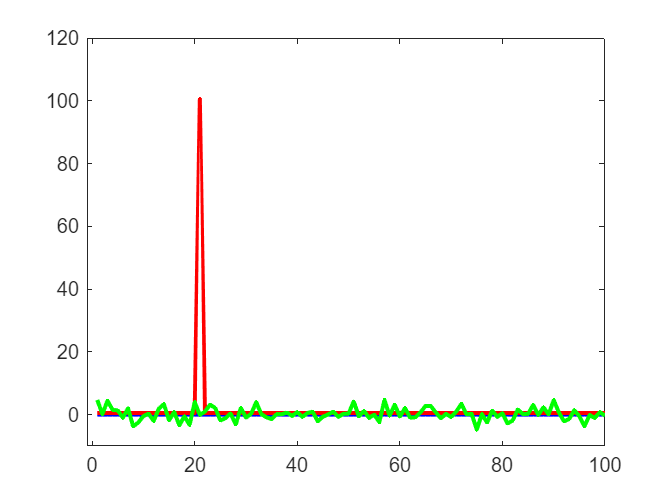

% Construction of the impulse nd gaussian noise plot
figure;
rng(4)
const=zeros(100,1);
plot(1:100,const,"blue","LineWidth",2);
xlim([-1,100]);
ylim([-10,120]);
hold on
impulse=[zeros(20,1);100;zeros(79,1)]+0.5;
gaussian=randn(100,1)*2;
plot(1:100,impulse,"red","LineWidth",2);
plot(1:100,gaussian,"green","LineWidth",2);
hold off

% Compute the errors
methods=["MAE","MSE"];

for i=1:2
    E2(i,1)=ErrorMeasure(const,impulse,methods(i));
    E2(i,2)=ErrorMeasure(const,gaussian,methods(i));
end

% Displaying the errors
array2table(E2,"VariableNames",["Impulse(red)","Gaussian(green)",],"RowNames",methods);

% PSNR:
% PSNR is infinite if the images are the same and becomes smaller the more
% different they are.
%
% Comparisions MSE and MAE:
% MSE: small inaccuracies are squared out and are not as important as large
% outliers.
% This is not the case with MAE.

Classes of Noise:

- Gaussian noise

- Multipicative gamma noise

- Impulsive noise

- Salt and pepper noise

- Poisson noise

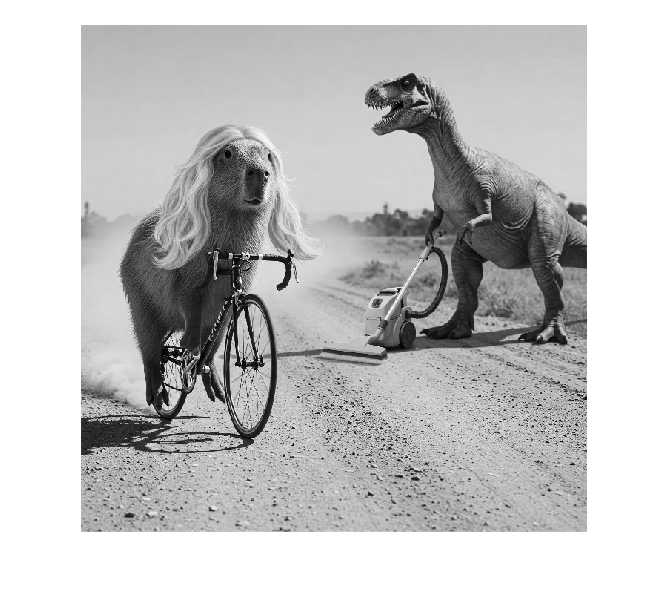

% load and examine the image
img=double(rgb2gray(imread("capybara.png")))./255;
imshow(img)

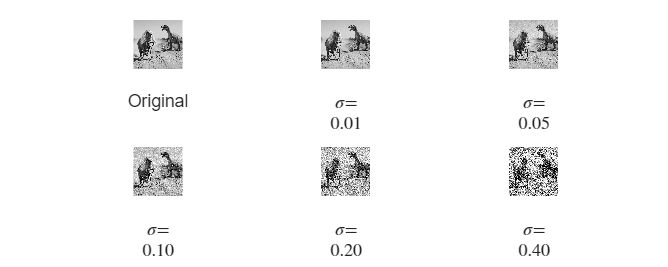

fig.Position(3:4)=[3000,1200];

subplot(1,2,1)
imshow(img)
subplot(1,2,2)
histogram(img,64) 

**White Gaussian noise is additive, i.e it applies**

                                            
$$f = u_0 + \eta $$


where $u_0$ is the original image and $\eta$ denotes the noise term, which can be modelled by a vector of random variables $X = (X_i)_{i=1}^{N}$, where the components $X_i$ are independent and identically distributed i.e. $X_i \, \tilde{} \, \mathcal{N}(0,\sigma^2),~i=1,\dots,N$.

Task: Model with Gaussian noise with variance $\sigma^2$ and add it to the image. Use the function randn and the following statement about the normal distribution.

If $X \tilde{} \mathcal{N}(0,1)$ and $Y \tilde{} \mathcal{N}(\mu,\sigma^2)$ then $Y = \sigma \cdot X + \mu$.

Compare the noisy image with the image that is obtained by the predefined Matlab commnand imnoise.

mu=0;
v=0.01;
% Adding the gaussian noise manually
rng("default")
noise=sqrt(v)*randn(size(img))+mu;
Gaussian1=img+noise;
Gaussian1(Gaussian1<0)=0;
Gaussian1(Gaussian1>1)=1

Gaussian1 =     0.7832    0.6698    0.7653    0.7013    0.7421    0.8611    0.7376    0.5862    0.6727    0.6402    0.7746    0.6666    0.7386    0.6309    0.8557    0.6672    0.6148    0.8767    0.7685    0.8794    0.7942    0.6396    0.8749    0.7785    0.7796    0.5185    0.8687    0.7927    0.6382    0.7741    0.7920    0.8077    0.7295    0.8013    0.7259    0.8701    0.7159    0.5821    0.7192    0.6750    0.7921    0.6742    0.7596    0.7024    0.6375    0.7437    0.7694    0.7835    0.6589    0.8890
    0.9089    0.6321    0.8307    0.9471    0.7198    0.8891    0.8557    0.8815    0.7847    0.7191    0.8616    0.6609    0.6215    0.6926    0.8473    0.7485    0.6728    0.6573    0.6112    0.8986    0.8301    0.7213    0.8725    0.7253    0.7480    0.7119    0.6348    0.9305    0.8345    0.6165    0.9288    0.8872    0.6732    0.6345    0.6474    0.6906    0.7339    0.7820    0.6710    0.7046    0.7094    0.7726    0.5535    0.5112    0.7240    0.7556    0.5091    0.6731    0.5

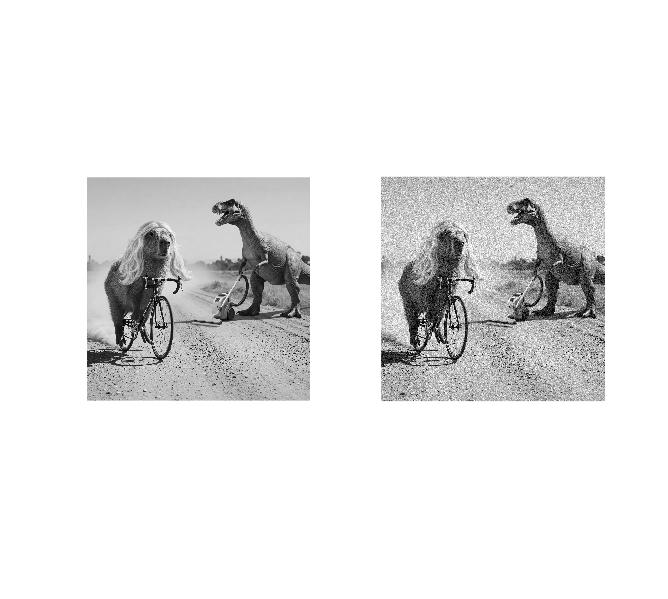

imshow(Gaussian1);

% Adding the gaussian noise by imnoise command
rng("default");
Gaussian2=imnoise(img,"gaussian",mu,v);

% Plotting both the plots next to each other
fig=figure;
fig.Position(3:4)=[3000,3000]

fig =   Figure (165) with properties:

      Number: 165
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 98 3000 3000]
       Units: 'pixels'

  Show all properties


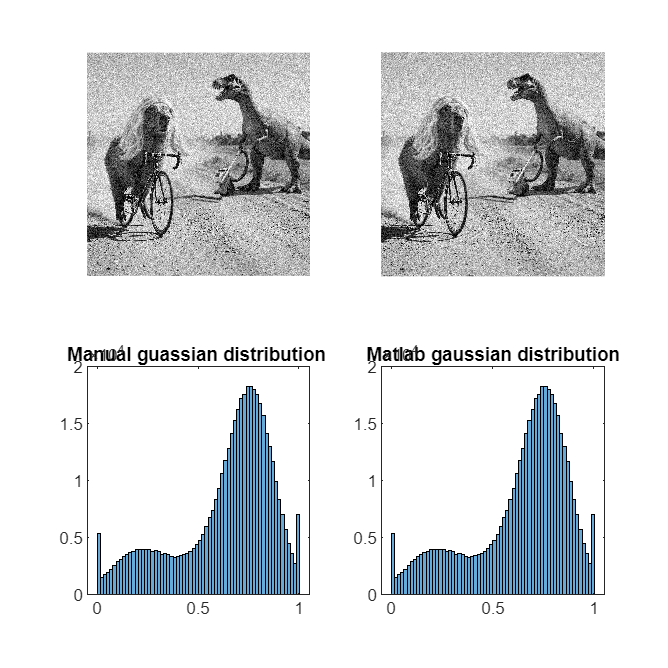

subplot(2,2,1)
imshow(Gaussian1)
subplot(2,2,2)
imshow(Gaussian2)
subplot(2,2,3)
histogram(Gaussian1,64)
title("Manual guassian distribution ")
subplot(2,2,4)
histogram(Gaussian2,64);title("Matlab gaussian distribution");

E=ErrorMeasure(Gaussian1, Gaussian2,"MSE");

E

E = 0

b) Gamma noise is a typical example of multipicative noise. It applies $f = u_0 \cdot \eta $

where $u_0$ denotes the original image and $\eta$ denotes the noise term, which can be modelled by a random vector $X = (X_i)_{i=1}^{N}$. The components  $X_i$ are independent and identically distributed with respect to the gamma distribution, , i.e. $X_i \, \tilde{} \, \Gamma(\alpha,\theta),~i=1,\dots,N$ where $\alpha>0 $ is the shape parameter and $\theta>0$ the scale parameter. The mean satisfies $\mu = \alpha\,\theta$ and the variance $\sigma^2 = \alpha \, \theta^2$. 

v=0.05

v = 0.0500

alpha=1/v;
theta=v;

rng("default");
% Model and multiply gamma noise
gamma_noise=gamrnd(alpha, theta, size(img));
gamma=img.*gamma_noise;
gamma=min(max(gamma,0),1)

gamma =     1.0000    0.6255    0.6405    1.0000    0.7819    0.6228    0.5984    0.6745    0.9076    0.5233    0.4934    0.6094    0.7183    0.5692    0.4011    1.0000    0.6570    0.6565    0.5036    0.6474    0.8252    0.5799    0.6167    0.6966    0.5937    0.7914    0.7978    0.5893    0.8742    0.9365    0.6937    0.6736    0.6975    0.7524    0.9526    0.5143    0.7136    0.7782    0.6067    0.7294    0.6156    0.5463    0.5581    0.8527    0.9465    0.8786    0.8301    0.6532    0.6738    0.8604
    0.8613    0.8803    0.5010    0.6666    0.5665    0.7528    0.4552    0.8390    0.7315    0.4478    0.8010    0.7243    0.5388    0.7636    0.5644    0.6262    0.9138    0.8412    0.6302    0.6105    0.7721    0.7124    0.7691    0.8309    0.6489    0.4607    0.8336    0.8028    0.4922    0.6843    0.5411    0.5773    0.8068    1.0000    0.9420    0.9039    0.5645    0.6571    0.5921    0.7264    0.8145    0.6096    0.5984    0.6970    0.8505    0.7680    0.9568    1.0000    0.4083 

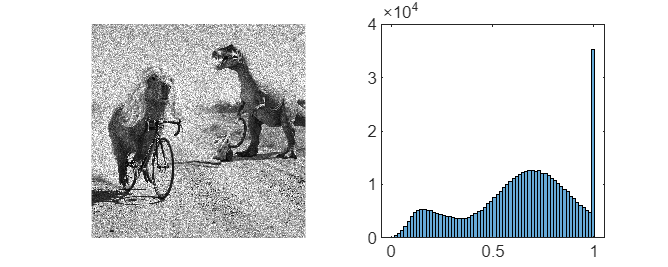

fig=figure;
fig.Position(3:4)=[3000,1200];
subplot(1,2,1);
imshow(gamma);
subplot(1,2,2);
histogram(gamma,64);

c) Impulsive noise is neither additive nor multipicative. It is modelled by replacing the color values in random pixels wit uniformly distributed color values independent of the initial values.

Task: Add $25 \%$ impulsive noise to the image.

Hint: The command

d=0.25;

% randomly draws 25% of the pixel indices
rng("default");
ind=randperm(numel(img));% Creates integers 
noisy_points=ind(1:round(numel(img)*d));
% Adding impulsive noise to the image
impulsive=img;
impulsive(noisy_points)=rand(1,length(noisy_points));

% plot the results
fig=figure;
fig.Position(3:4)=[3000,1200]

fig =   Figure (167) with properties:

      Number: 167
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 98 3000 1200]
       Units: 'pixels'

  Show all properties


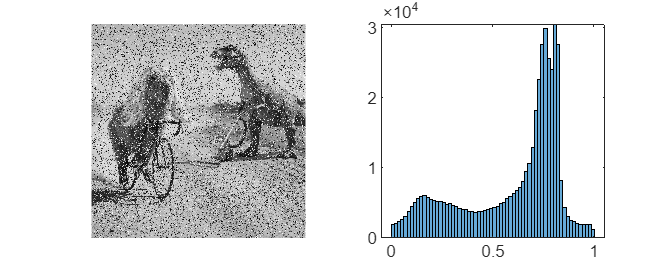

subplot(1,2,1)
imshow(impulsive)
subplot(1,2,2)
histogram(impulsive,64)

d) Salt-pepper noise: is a special case of impulsive  noise to the image manually. Here the color values are no

Create a second noisy image with the imnoise command and compare the two noisy images.

d=0.25;

% randomly draw 25% of the pixel indices
rng("default");
ind=randperm(numel(img))

ind =       230491      249912      276719      152148       51110      220306      165529      308499      435324      242710      253414      138533       66611       70566      356823      185502       16503       35805      339573       83311        9320       16469       88237       28954       10618      433536      399706      317852      410724      287909        8137      391200      306331      449940       54669      402594      429334      341827      444832      365638      141473      268321       45022       99617       78512      158536      250026      303390       12133      277323


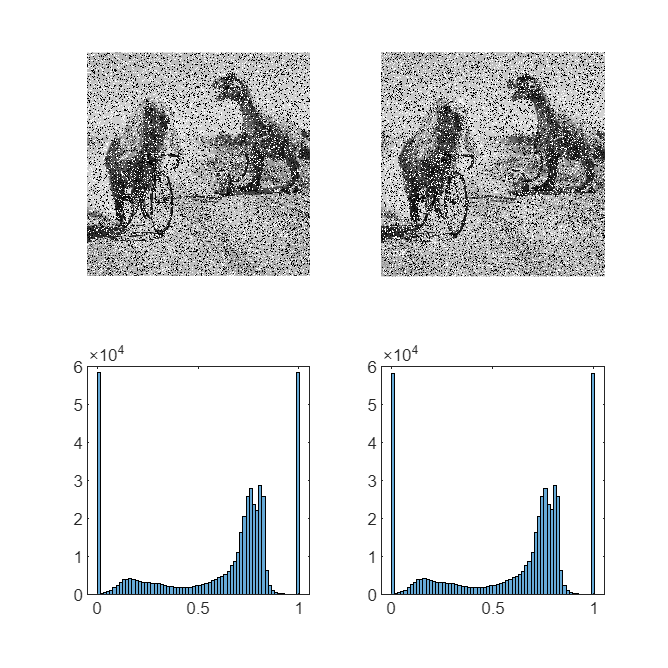

noisy_points=ind(1:round(numel(img)*d));

% Add salt and pepper noise to the image
saltandpepper1=img;
saltandpepper1(noisy_points)=round(rand(1,length(noisy_points)));

rng("default");
saltandpepper2=imnoise(img,"salt & pepper",d);

% Plot both images
fig=figure;
fig.Position(3:4)=[3000,3000];
subplot(2,2,1)
imshow(saltandpepper1);
subplot(2,2,2)
imshow(saltandpepper2);
subplot(2,2,3)
histogram(saltandpepper1,64);
subplot(2,2,4)
histogram(saltandpepper2,64);

d) Poisson noise is neither additive nor multiplicative. Let $u_0$ be an original un-noised image, then we can model the components of the Poisson-noise image $u = (u_i)_{i=1}^N$ by $u_i \, \tilde{} \, Pois(u^0_i)$ for $i=1,\dots,N$.

*Task:* Use the command` poissrnd `from the *Statistics and Machine Learning Toolbox* and generate the poisson noise manually

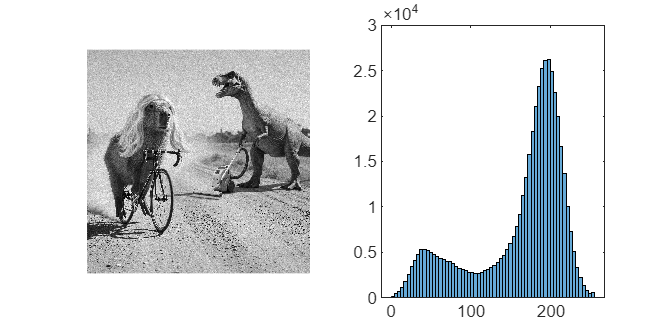

rng("default");
poisson=uint8(poissrnd(round(img*255)));

% Plot both images
fig=figure;
fig.Position(3:4)=[3000,1500];
subplot(1,2,1);
imshow(poisson);
subplot(1,2,2);histogram(poisson,64);

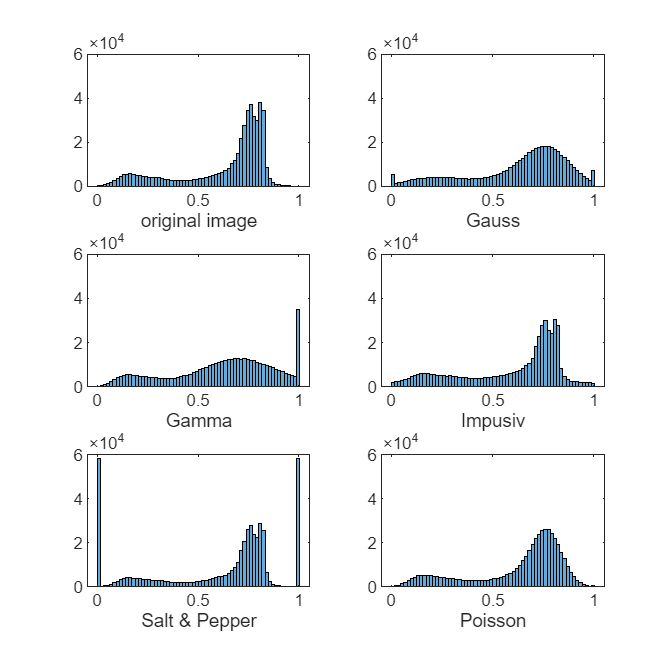

% plot all the histograms
fig=figure;
fig.Position(3:4)=[3000,3000];
subplot(3,2,1);
histogram(img,64);
ylim([0,6*10^4]);
xlabel("original image");

subplot(3,2,2);
histogram(Gaussian1,64);
ylim([0,6*10^4]);
xlabel("Gauss");

subplot(3,2,3);
histogram(gamma,64);
ylim([0,6*10^4])
xlabel('Gamma')
subplot(3,2,4)
histogram(impulsive,64)
ylim([0,6*10^4])
xlabel('Impusiv')
subplot(3,2,5)
histogram(saltandpepper1,64)
ylim([0,6*10^4])
xlabel('Salt & Pepper')

subplot(3,2,6)
histogram(double(poisson)/255,64)
ylim([0,6*10^4])
xlabel('Poisson')

## Part 2: Smoothing of Images

You will need the Image Processing Toolbox of Matlab (Installation: Home -> Add-Ons -> Image Processing Toolbox).

In the following we take a look on different linear filters and nonlinear filters. Therefore we will test this filters on the images` capybara_Gaussian.png `(white Gaussian noise) and` capybara_SaP.png `(salt-and-pepper noise).

capy = rgb2gray(double(imread('capybara.png'))/255);
figure
imshow(capy)

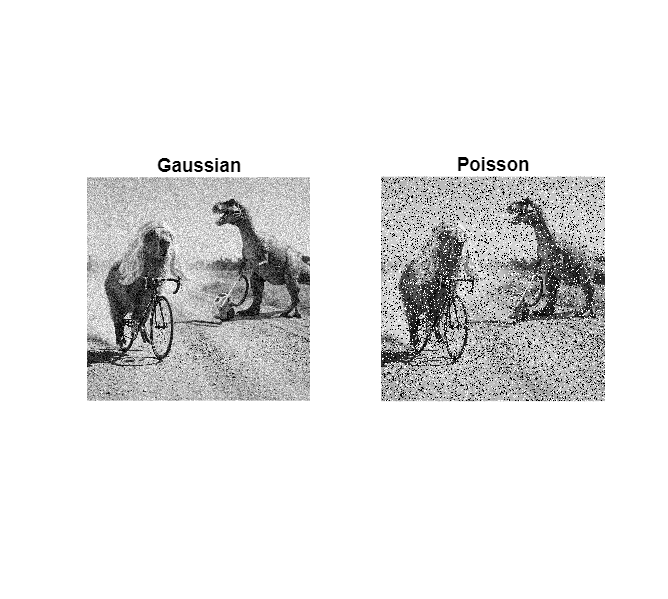

subplot(1,2,1);
capy1 = imnoise(capy,'gaussian');
imshow(capy1);
title("Gaussian")

subplot(1,2,2);
capy2 = imnoise(capy,'salt & pepper',0.2);
imshow(capy2);title("Poisson");

**Linear Smoothening filters:**

**a) Mean filter:**

**The means filter is the simplest example of a linear filter**

**Implement a function U= mean_filter(F,s) that uses the mean filter on te image F. Therefore each pixel is replaced by the mean value of the neighbouring pixels. The neighbourood is described by (2s+1)x(2s+1) centered on the pixel is replaced.**

% apply the mean filters to the image
fig=figure;
fig.Position(3:4)=[3000,1500];
subplot(1,2,1);
imshow(mean_filter())





